clc
clear
% Parameters
M1 = 10;  % Mass of the trolley (kg)
M2 = 10;  % Mass of the pendulum (kg)
L = 0.1;   % Length of the pendulum (m)
k = 5000.0;  % Spring constant (N/m)
g = 9.81;  % Acceleration due to gravity (m/s^2)

% Time settings
dt = 0.001;  % Time step (s)
t_final = 5;  % Final time (s)
t = 0:dt:t_final;  % Time vector

% Visualization parameters
updateFrequency = 10;  % Update the plot every 'updateFrequency' iterations
springHeight = 0.012;  % Amplitude of the spring waveform
springOffset = 0.0;
lineHeight = -0.025;    % Y position of the line the trolley slides on
trolleyHeight = 0.05;   % Height of the trolley rectangle
trolleyWidth = 0.1;     % Width of the trolley rectangle
trolleyYOffset = 2 * lineHeight + trolleyHeight / 2;  % Y offset to position the trolley above the line

% Initialize vectors for position, velocity, and acceleration
x = zeros(size(t));
theta = zeros(size(t));
v = zeros(size(t));
omega = zeros(size(t));
a = zeros(size(t));  % Acceleration of the trolley
alpha = zeros(size(t));  % Angular acceleration of the pendulum
% Initialize arrays for the bob's position
x_bob = zeros(size(t));
y_bob = zeros(size(t));
L_actual = zeros(size(t));

theta0 = 0 * (pi/180);  % Initial angle (radians)
omega0 = 0;  % Initial angular velocity (rad/s)
x0 = 0.02;      % Initial displacement of trolley (m)
v0 = 0;      % Initial velocity of trolley (m/s)
% Set initial conditions
x(1) = x0;
theta(1) = theta0;
v(1) = v0;
omega(1) = omega0;

% Euler integration
for i = 1:length(t) - 1
        
    % Calculate accelerations
    a(i+1) = ( -M2*L*cos(theta(i))*alpha(i) + M2*L*sin(theta(i))*omega(i)^2 - k*x(i) )/(M1+M2);

    %fprintf('a(%d) = (-%f * %f * cos(%f) * %f + %f * %f * sin(%f) * %f^2 - %f * %f) / (%f + %f) = %f\n', ...
     %   i, M2, L, theta(i), alpha(i), M2, L, theta(i), omega(i), k, x(i), M1, M2, a(i));
    alpha(i+1) = ( -cos(theta(i))*a(i+1) - g*sin(theta(i)) )/L ;
    %alpha(i) = (-g * sin(theta(i)) - a(i) * cos(theta(i))) / L;
    
    % Update velocities and positions
    v(i + 1) = v(i) + a(i) * dt;
    omega(i + 1) = omega(i) + alpha(i) * dt;
    x(i + 1) = x(i) + v(i) * dt;
    theta(i + 1) = theta(i) + omega(i) * dt;

    % Calculate the position of the pendulum's bob at each time step
    x_bob(i) = x(i) + L * sin(theta(i));
    y_bob(i) = -L * cos(theta(i));

    % Calculate the actual rod length (should be constant if L is constant)
    L_actual(i) = sqrt((x_bob(i) - x(i))^2 + y_bob(i)^2);
end

% After the loop, you should also update the last position of the bob
x_bob(end) = x(end) + L * sin(theta(end));
y_bob(end) = -L * cos(theta(end));
L_actual(end) = sqrt((x_bob(end) - x(end))^2 + y_bob(end)^2);

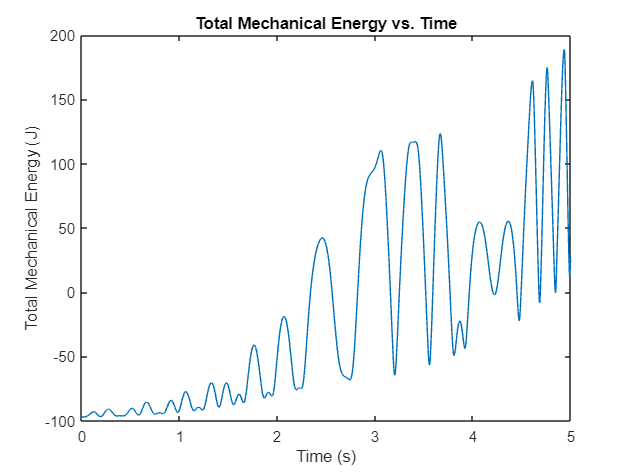

for i = 1:length(t)
    % Update the state variables (x, v, theta, theta_dot)
    % Your existing code for state updates goes here
    
    % Calculate the total mechanical energy
    
    Ttotal = (0.5 * (M1+M2) * v(i)^2) + (0.5 * M2 * (L^2) * omega(i)^2) + (M2*L*cos(theta(i))*v(i)*omega(i));
    Vtotal = 0.5*k*x(i)^2 - M2*g*cos(theta(i));
    
    E(i) = Ttotal + Vtotal; % Store the energy value at this time step
end

figure;
plot(t, E);
xlabel('Time (s)');
ylabel('Total Mechanical Energy (J)');
title('Total Mechanical Energy vs. Time');

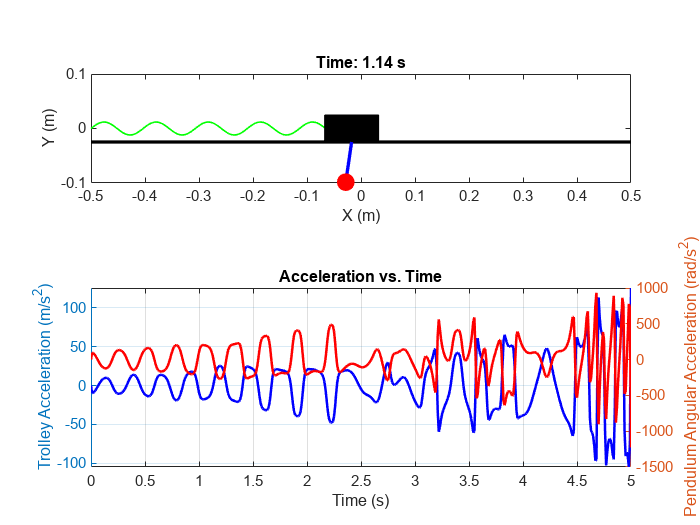


% Visualization parameters
updateFrequency = 10;  % Update the plot every 'updateFrequency' iterations
springHeight = 0.012;  % Amplitude of the spring waveform
springOffset = 0.0;
lineHeight = -0.025;    % Y position of the line the trolley slides on
trolleyHeight = 0.05;   % Height of the trolley rectangle
trolleyWidth = 0.1;     % Width of the trolley rectangle
trolleyYOffset = 2 * lineHeight + trolleyHeight / 2;  % Y offset to position the trolley above the line

% Initialize figure
figure;

% Lower subplots for acceleration plots
subplot(2, 1, 2);
% Trolley acceleration plot
yyaxis left;
plot(t(1:10:end), a(1:10:end), 'b-', 'LineWidth', 1.5);  % Acceleration of the trolley
ylabel('Trolley Acceleration (m/s^2)');
xlabel('Time (s)');
yyaxis right;

% Pendulum angular acceleration plot
plot(t(1:10:end), alpha(1:10:end), 'r-', 'LineWidth', 1.5);  % Angular acceleration of the pendulum
ylabel('Pendulum Angular Acceleration (rad/s^2)');
xlabel('Time (s)');
title('Acceleration vs. Time');
grid on;

% Visualization loop
for i = 1:length(t)
    if mod(i, updateFrequency) == 0  % Check if it's time to update the plot
        
        % Calculate the position of the pendulum's bob for plotting
        pendulum_x = x_bob(i);
        pendulum_y = y_bob(i);
        
        % Calculate the end points of the rod based on the trolley and bob positions
        rod_x = [x(i), pendulum_x];
        rod_y = [trolleyYOffset, pendulum_y];
        
        % Plot the rod
        subplot(2, 1, 1);
        plot(rod_x, rod_y, 'b-', 'LineWidth', 2);
        hold on;
        
        % Spring visualization parameters
        springRestLength = 0.5;  % Rest length of the spring (m)
        springAmplitude = springHeight; % Amplitude of the spring waveform
        numCoils = 10;           % Number of coils in the spring at rest
        
        % Calculate the spring length based on the trolley position
        springLength = x(i) + springRestLength; % x(i) is negative when compressed
        springCompression = springRestLength - springLength; % Positive when compressed
        frequencyAdjustment = springRestLength / springLength; % Increase freq when compressed
        
        % Calculate the spring endpoints
        springX = linspace(-0.5, x(i), 200); % Use more points for a smoother spring
        springY = springAmplitude * sin(2 * pi * frequencyAdjustment * numCoils * (springX + 0.5));
        
        % Plot the spring with the corrected connection to the trolley
        subplot(2, 1, 1);
        plot(springX, springY, 'g-', 'LineWidth', 1);
        hold on;
        
        % Plot the black line (ground) below the trolley
        plot([-0.5, 0.5], [lineHeight, lineHeight], 'k-', 'LineWidth', 2);
        
        % Plot the trolley with the corrected position above the ground
        rectangle('Position', [x(i) - trolleyWidth/2, trolleyYOffset, trolleyWidth, trolleyHeight], 'FaceColor', 'k');
        
        % Plot the pendulum with the corrected connection to the trolley
        plot([x(i), pendulum_x], [trolleyYOffset, pendulum_y], 'b-', 'LineWidth', 2);  % Rod
        plot(pendulum_x, pendulum_y, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');  % Mass
        
        % Set plot limits and labels
        subplot(2, 1, 1);
        axis equal;
        xlim([-0.5, 0.5]);
        ylim([-0.1, 0.1]);
        xlabel('X (m)');
        ylabel('Y (m)');
        title(sprintf('Time: %.2f s', t(i)));
        
        % Ensure the plot is updated correctly
        drawnow;
        
        % Release the hold to update in the next iteration
        hold off;
    end
    % Pause is not necessary here as drawnow will update the plot visuals
end